依赖[统一实验分析作图v18.1.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

Similar activity in MOp Learned_task_A and Transfer_task_B

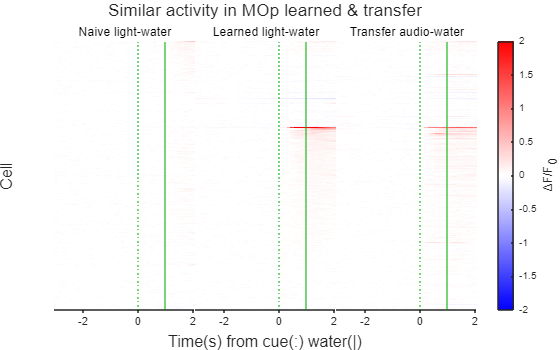

Fig=figure;
Layout=tiledlayout(1,2,TileSpacing='tight',Padding='tight');
Axes(1)=nexttile(Layout,1);
PcaLegend=TransferLearning.TransferSimilarity(TransferLearning.Flags.LightAudio|TransferLearning.Flags.PPT|TransferLearning.Flags.MOp,[1:3],PcaAx=Axes(1));

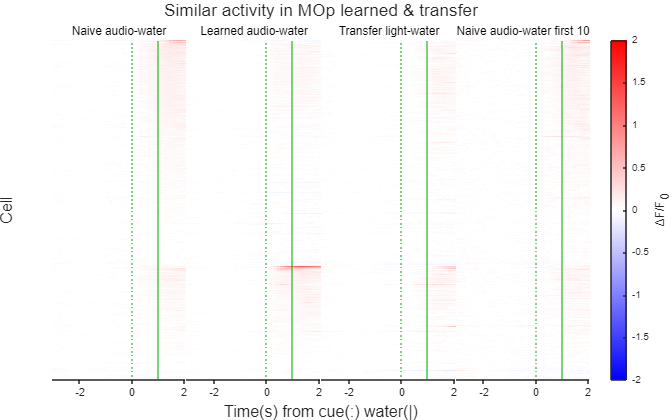

% PcaLegend.Location='southwest';
Axes(2)=nexttile(Layout,2);
PcaLegend=TransferLearning.TransferSimilarity(TransferLearning.Flags.AudioLight|TransferLearning.Flags.PPT|TransferLearning.Flags.MOp,[1:3],HeatmapScale=MATLAB.Flags.Amplify,PcaAx=Axes(2));

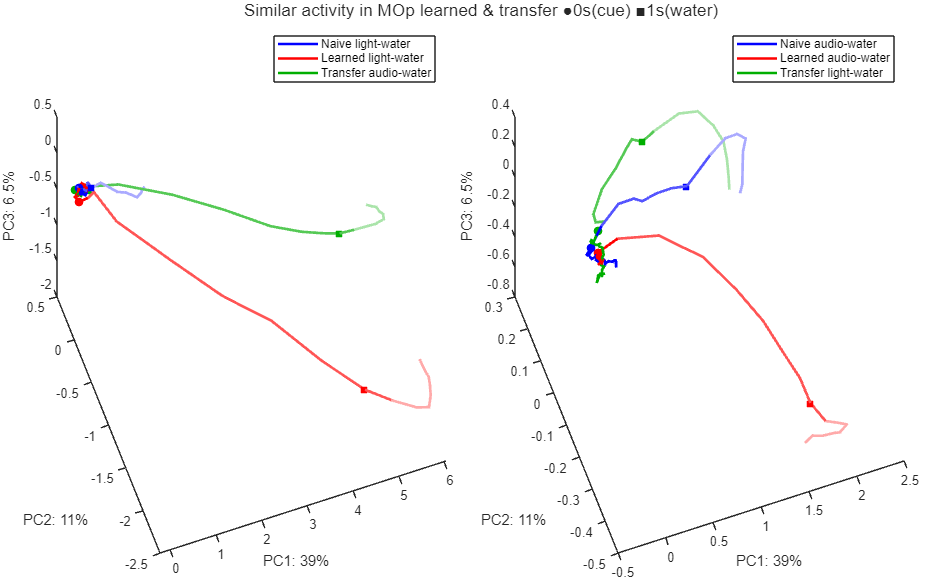

% PcaLegend.Location='southwest';
title(Layout,'Similar activity in MOp learned & transfer ●0s(cue) ■1s(water)');
UniExp.PcaRotate(Axes);
MATLAB.Graphics.FigureAspectRatio(8,5,2,Fig);
print(Fig,TransferLearning.ProjectPath('迁移PCA.png'),'-dpng','-r300');